# HRA of TF-IDF-rank signal

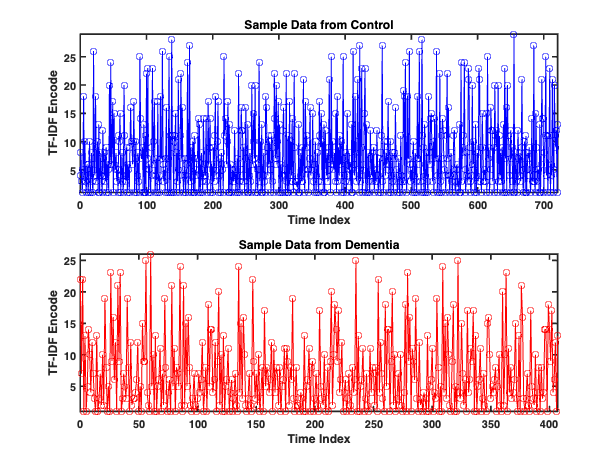

clc
clearvars
close all

data_dir1 = fullfile(pwd,"data/hra/tf-idf_control/");
data_dir2 = fullfile(pwd,"data/hra/tf-idf_dementia/");

fnames_hc = dir(data_dir1);
fnames_hc = fnames_hc(~ismember({fnames_hc.name},{'.','..'}));
fnames_ad = dir(data_dir2);
fnames_ad = fnames_ad(~ismember({fnames_ad.name},{'.','..'}));

x1 = readtable(fullfile(data_dir1,fnames_hc(1).name));
x2 = readtable(fullfile(data_dir2,fnames_ad(1).name));

subplot(2,1,1)
plot(x1.index,x1.x,'-o','Color','blue')
axis tight
title("Sample Data from Control")
xlabel("Time Index")
ylabel("TF-IDF Encode")
set(gca,'FontWeight','bold','LineWidth',1.5)

subplot(2,1,2)
plot(x2.index,x2.x,'-o','Color','red')
axis tight
title("Sample Data from Dementia")
xlabel("Time Index")
ylabel("TF-IDF Encode")
set(gca,'FontWeight','bold','LineWidth',1.5)

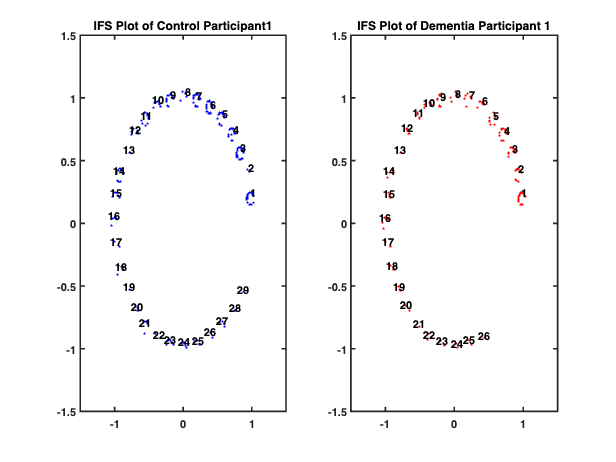

num_id = 32;
alpha = 0.05;

sig1 = x1.x;
ifs_hc = IFS(sig1,num_id,alpha);
sig2 = x2.x;
ifs_ad = IFS(sig2,num_id,alpha);
ifs_hc(1,:) = [];
ifs_ad(1,:) = [];

subplot(1,2,1)
plot(ifs_hc(:,1),ifs_hc(:,2),'.','Color','b')
for i=1:num_id
    id_idx = find(sig1 == i);
    c = mean(ifs_hc(id_idx,:),1);
    text(c(1)+0.08,c(2)+0.08,num2str(i),'FontWeight','bold',...
        'VerticalAlignment','top','HorizontalAlignment','right')
end
ylim([-1.5,1.5])
xlim([-1.5,1.5])
title('IFS Plot of Control Participant1')
set(gca,'LineWidth',1.5,'FontWeight','bold')
subplot(1,2,2)
plot(ifs_ad(:,1),ifs_ad(:,2),'.','Color','r')
for i=1:num_id
    id_idx = find(sig2 == i);
    c = mean(ifs_ad(id_idx,:),1);
    text(c(1)+0.08,c(2)+0.08,num2str(i),'FontWeight','bold',...
        'VerticalAlignment','top','HorizontalAlignment','right')
end
ylim([-1.5,1.5])
xlim([-1.5,1.5])
title('IFS Plot of Dementia Participant 1')
set(gca,'LineWidth',1.5,'FontWeight','bold')

fsize1 = size(fnames_hc,1);
fsize2 = size(fnames_ad,1);
num_feat = 4;
s = num_id*num_feat;
feat_mx = NaN(fsize1+fsize2,num_id*num_feat+num_id^2*num_feat);

alpha = 0.04;
nbins = 0;

for i=1:fsize1
    if mod(i,10) == 0
        out = sprintf("HC File [%i/%i]", i, fsize2);
        disp(out);
    end
    
    csig = readtable(fullfile(data_dir1,fnames_hc(i).name));
    csig = csig.x + 1;
    ifs_add = IFS(csig,num_id,alpha);
    
    % 1st order
    for j=1:num_id
        [feat_mx(i,j),feat_mx(i,j+num_id),feat_mx(i,j+num_id*2),feat_mx(i,j+num_id*3)] = ...
            heterorecurrence(ifs_add,csig,j);
        % 2nd order
        for k=1:num_id
            [feat_mx(i,k+s*j),feat_mx(i,k+s*j+num_id),feat_mx(i,k+s*j+num_id*2),feat_mx(i,k+s*j+num_id*3)] = ...
                heterorecurrence2(ifs_add,csig,j,k);
        end
    end
end

HC File [10/309]
HC File [20/309]
HC File [30/309]
HC File [40/309]
HC File [50/309]
HC File [60/309]
HC File [70/309]
HC File [80/309]
HC File [90/309]
HC File [100/309]
HC File [110/309]
HC File [120/309]
HC File [130/309]
HC File [140/309]
HC File [150/309]
HC File [160/309]
HC File [170/309]
HC File [180/309]
HC File [190/309]
HC File [200/309]
HC File [210/309]
HC File [220/309]
HC File [230/309]
HC File [240/309]



for i=1:fsize2
    if mod(i,10) == 0
        out = sprintf("AD File [%i/%i]", i, fsize2);
        disp(out)
    end

    csig = readtable(fullfile(data_dir2,fnames_ad(i).name));
    csig = csig.x + 1;
    ifs_add = IFS(csig,num_id,alpha);

    % 1st order
    for j=1:num_id
        [feat_mx(fsize1+i,j),feat_mx(fsize1+i,j+num_id),feat_mx(fsize1+i,j+num_id*2),feat_mx(fsize1+i,j+num_id*3)] = ...
            heterorecurrence(ifs_add,csig,j);
        % 2nd order
        for k=1:num_id
            [feat_mx(fsize1+i,k+96*j),feat_mx(fsize1+i,k+96*j+num_id),feat_mx(fsize1+i,k+96*j+num_id*2),feat_mx(fsize1+i,k+s*j+num_id*3)] = ...
                heterorecurrence2(ifs_add,csig,j,k);
        end
    end
end

AD File [10/309]
AD File [20/309]
AD File [30/309]
AD File [40/309]
AD File [50/309]
AD File [60/309]
AD File [70/309]
AD File [80/309]
AD File [90/309]
AD File [100/309]
AD File [110/309]
AD File [120/309]
AD File [130/309]
AD File [140/309]
AD File [150/309]
AD File [160/309]
AD File [170/309]
AD File [180/309]
AD File [190/309]
AD File [200/309]
AD File [210/309]
AD File [220/309]
AD File [230/309]
AD File [240/309]
AD File [250/309]
AD File [260/309]
AD File [270/309]
AD File [280/309]
AD File [290/309]
AD File [300/309]


# HRA of dictionary order signal

clc
clearvars
close all

data_dir1 = fullfile(pwd,"data/hra/control/");
data_dir2 = fullfile(pwd,"data/hra/dementia/");

fnames_hc = dir(data_dir1);
fnames_hc = fnames_hc(~ismember({fnames_hc.name},{'.','..'}));
fnames_ad = dir(data_dir2);
fnames_ad = fnames_ad(~ismember({fnames_ad.name},{'.','..'}));

num_id = 32;

## Plot sample data

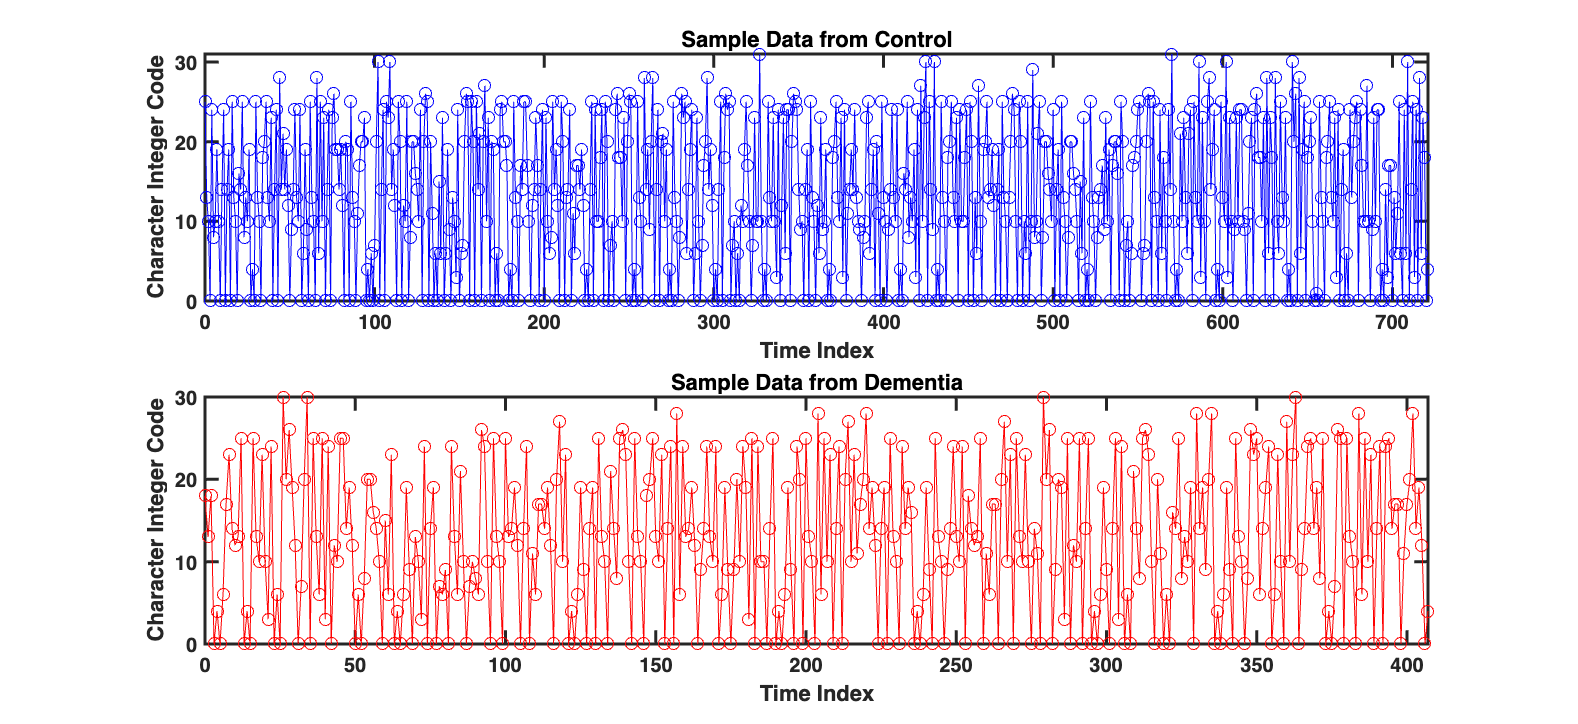

x1 = readtable(fullfile(data_dir1,fnames_hc(1).name));
x2 = readtable(fullfile(data_dir2,fnames_ad(1).name));

figure('Color','w','Position',[100,100,1200,550])
subplot(2,1,1)
plot(x1.index,x1.x,'-o','Color','blue')
axis tight
title("Sample Data from Control")
xlabel("Time Index")
ylabel("Character Integer Code")
set(gca,'FontWeight','bold','LineWidth',1.5)

subplot(2,1,2)
plot(x2.index,x2.x,'-o','Color','red')
axis tight
title("Sample Data from Dementia")
xlabel("Time Index")
ylabel("Character Integer Code")
set(gca,'FontWeight','bold','LineWidth',1.5)

for i=0:(num_id-1)
    id_idx = find(x1.x == i);
    s = sprintf('ID %i: %i', i+1, length(id_idx));
    disp(s)
end

ID 1: 150
ID 2: 1
ID 3: 0
ID 4: 9
ID 5: 17
ID 6: 0
ID 7: 31
ID 8: 8
ID 9: 11
ID 10: 13
ID 11: 80
ID 12: 7
ID 13: 12
ID 14: 38
ID 15: 44
ID 16: 2
ID 17: 6
ID 18: 15
ID 19: 16
ID 20: 32
ID 21: 44
ID 22: 6
ID 23: 0
ID 24: 35
ID 25: 46
ID 26: 62
ID 27: 12
ID 28: 4
ID 29: 10
ID 30: 1
ID 31: 8
ID 32: 2


for i=0:(num_id-1)
    id_idx = find(x2.x == i);
    s = sprintf('ID %i: %i', i+1, length(id_idx));
    disp(s)
end

ID 1: 85
ID 2: 0
ID 3: 0
ID 4: 6
ID 5: 10
ID 6: 0
ID 7: 24
ID 8: 4
ID 9: 7
ID 10: 14
ID 11: 35
ID 12: 6
ID 13: 11
ID 14: 22
ID 15: 31
ID 16: 1
ID 17: 3
ID 18: 9
ID 19: 4
ID 20: 24
ID 21: 16
ID 22: 3
ID 23: 0
ID 24: 15
ID 25: 22
ID 26: 34
ID 27: 7
ID 28: 4
ID 29: 7
ID 30: 0
ID 31: 4
ID 32: 0


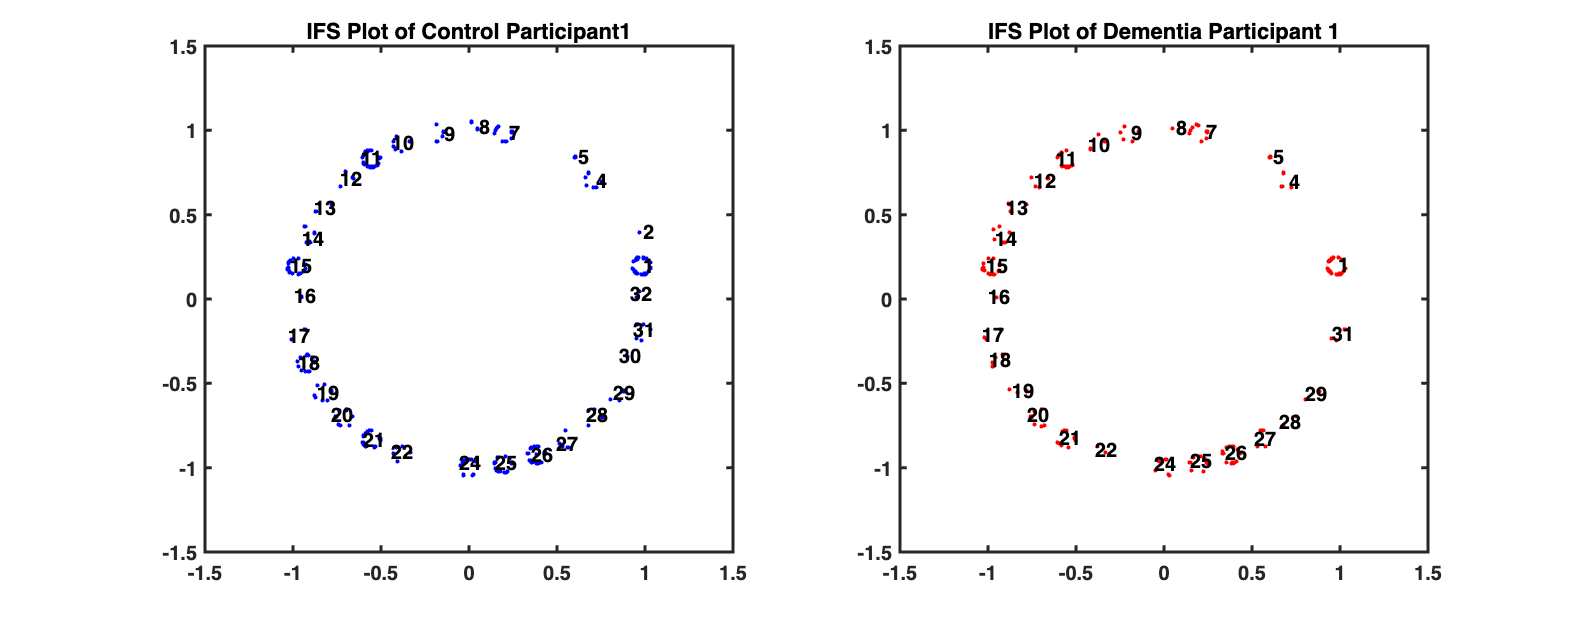

alpha = 0.05;
sig1 = x1.x + 1;
ifs_hc = IFS(sig1,num_id,alpha);
sig2 = x2.x + 1;
ifs_ad = IFS(sig2,num_id,alpha);
ifs_hc(1,:) = [];
ifs_ad(1,:) = [];

figure('Color','w','Position',[0,0,1400,550]);
subplot(1,2,1)
plot(ifs_hc(:,1),ifs_hc(:,2),'.','Color','b')
for i=1:num_id
    id_idx = find(sig1 == i);
    c = mean(ifs_hc(id_idx,:),1);
    text(c(1)+0.08,c(2)+0.08,num2str(i),'FontWeight','bold',...
        'VerticalAlignment','top','HorizontalAlignment','right')
end
title('IFS Plot of Control Participant1')
set(gca,'LineWidth',1.5,'FontWeight','bold')
subplot(1,2,2)
plot(ifs_ad(:,1),ifs_ad(:,2),'.','Color','r')
for i=1:num_id
    id_idx = find(sig2 == i);
    c = mean(ifs_ad(id_idx,:),1);
    text(c(1)+0.08,c(2)+0.08,num2str(i),'FontWeight','bold',...
        'VerticalAlignment','top','HorizontalAlignment','right')
end
title('IFS Plot of Dementia Participant 1')
set(gca,'LineWidth',1.5,'FontWeight','bold')

## Quantifications of IFS patterns

fsize1 = size(fnames_hc,1);
fsize2 = size(fnames_ad,1);
feat_mx = NaN(fsize1+fsize2,32*3+32*32*3);

alpha = 0.04;
nbins = 0;

for i=1:fsize1
%     out = sprintf("HC File [%i/%i]", i, fsize2);
%     disp(out);
    
    csig = readtable(fullfile(data_dir1,fnames_hc(i).name));
    csig = csig.x + 1;
    ifs_add = IFS(csig,num_id,alpha);
    
    % 1st order
    for j=1:num_id
        [feat_mx(i,j),feat_mx(i,j+num_id),feat_mx(i,j+num_id*2)] = ...
            heterorecurrence(ifs_add,csig,j,nbins);
        % 2nd order
        for k=1:num_id
            [feat_mx(i,k+96*j),feat_mx(i,k+96*j+num_id),feat_mx(i,k+96*j+num_id*2)] = ...
                heterorecurrence2(ifs_add,csig,j,k);
        end
    end
end

for i=1:fsize2
%     out = sprintf("AD File [%i/%i]", i, fsize2);
%     disp(out)

    csig = readtable(fullfile(data_dir2,fnames_ad(i).name));
    csig = csig.x + 1;
    ifs_add = IFS(csig,num_id,alpha);

    % 1st order
    for j=1:num_id
        [feat_mx(fsize1+i,j),feat_mx(fsize1+i,j+num_id),feat_mx(fsize1+i,j+num_id*2)] = ...
            heterorecurrence(ifs_add,csig,j,nbins);
        % 2nd order
        for k=1:num_id
            [feat_mx(fsize1+i,k+96*j),feat_mx(fsize1+i,k+96*j+num_id),feat_mx(fsize1+i,k+96*j+num_id*2)] = ...
                heterorecurrence2(ifs_add,csig,j,k);
        end
    end
end

# Variable screening (PCA/KS Test)

clc
close all
clearvars

load(fullfile(pwd,"data","hra","hrq_mx.mat"))
num_id = 32;

## PCA without removing zero columns

w = 1./(var(feat_mx)+eps);
[~,score,~,~,explained] = pca(feat_mx,'VariableWeights',w);

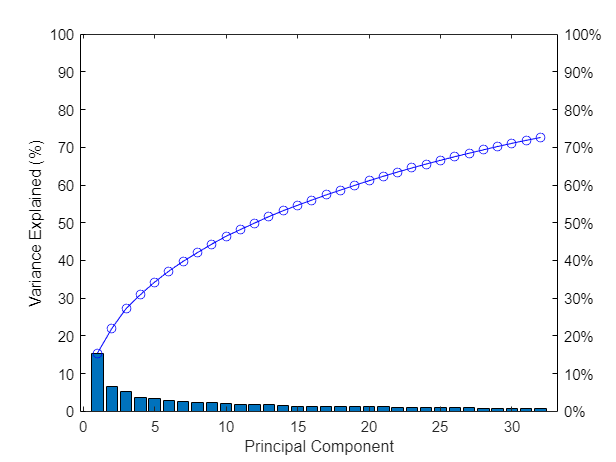

percent_ticks = string(0:10:100);
for i=1:length(percent_ticks)
    percent_ticks(i) = strcat(percent_ticks(i),"%");
end

figure
yyaxis left
bar(explained(1:num_id))
ylim([0,100])
set(get(gca,'YLabel'), 'String','Variance Explained (%)')
set(gca, 'YColor','black')
yyaxis right
plot(1:num_id,cumsum(explained(1:num_id)),'o-','Color','blue')
ylim([0,100])
yticklabels(percent_ticks)
set(gca, 'YColor','black')
xlabel('Principal Component')

## Remove zeros columns and perform the KS test

zidx = all(feat_mx==0,1);
feat_mx(:,zidx) = [];
num_hc = 243;

out_mx = NaN(size(feat_mx,2),4);
out_mx(:,4) = find(~zidx)';
for i=1:size(feat_mx,2)
    [out_mx(i,1),out_mx(i,2),out_mx(i,3)] = kstest2(feat_mx(1:num_hc,i),feat_mx(num_hc+1:end,i), ...
        'Alpha',0.05,'Tail','unequal');
end

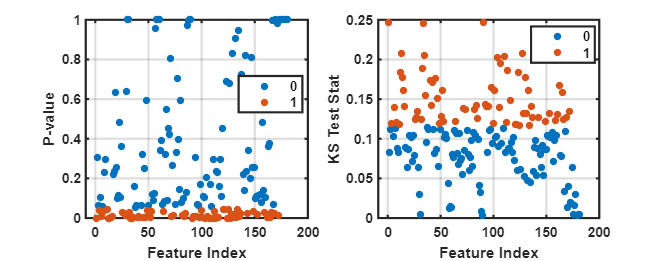

g = categorical(out_mx(:,1));
cidx = 1:size(feat_mx,2);

f = figure('Color','w','Position',[0,0,980,385]);
subplot(1,2,1)
gscatter(cidx,out_mx(:,2),g)
grid on
xlabel("Feature Index")
ylabel("P-value")
set(gca,'FontWeight','bold','LineWidth',1.5)

subplot(1,2,2)
gscatter(cidx,out_mx(:,3),g)
grid on
xlabel("Feature Index")
ylabel("KS Test Stat")
set(gca,'FontWeight','bold','LineWidth',1.5)

disp(out_mx(out_mx(:,3)>0.2,4)')

           1          13          35          36          97         517         711        1261



## Visualization of the distributional differneces of features

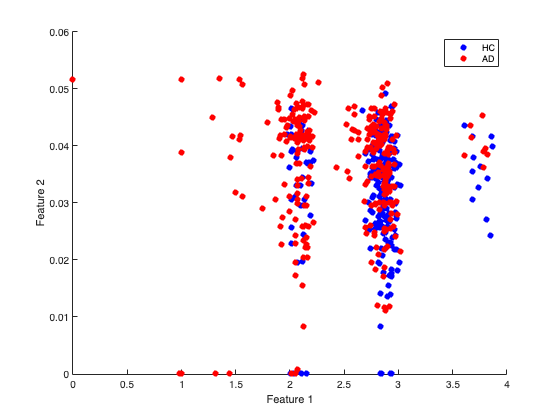

[~,max_idx] = maxk(out_mx(:,3),4);
i1 = max_idx(1);
i2 = max_idx(2);
figure('Color','w')
scatter(feat_mx(1:num_hc,i1),feat_mx(1:num_hc,i2),'filled','MarkerFaceColor','b')
hold on
scatter(feat_mx((num_hc+1):end,i1),feat_mx((num_hc+1):end,i2),'filled','MarkerFaceColor','r')
hold off
xlabel("Feature 1")
ylabel("Feature 2")
legend(["HC","AD"])

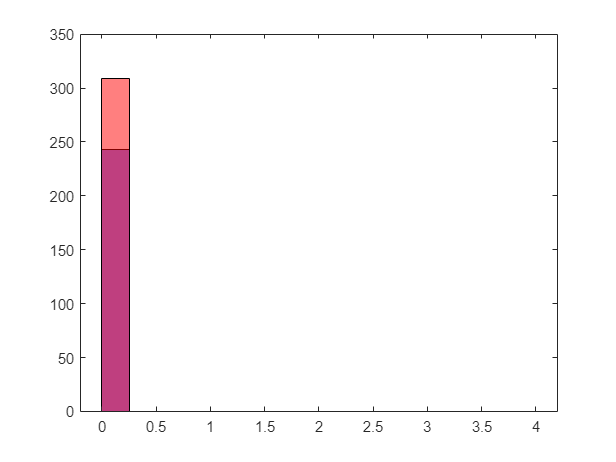

histogram(feat_mx(1:num_hc,i1),0:0.25:4,'FaceColor','b','FaceAlpha',0.5)
hold on
histogram(feat_mx(num_hc+1:end,i1),0:0.25:4,'FaceColor','r','FaceAlpha',0.5)
hold off

train classifiers

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Lambda |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.38914 |      1.2878 |     0.38914 |     0.38914 |     0.013558 |
|    2 | Best   |     0.31448 |     0.69303 |     0.31448 |       0.319 |   3.9555e-08 |
|    3 | Accept |     0.38688 |     0.33822 |     0.31448 |     0.31449 |   6.0831e-05 |
|    4 | Accept |     0.43891 |     0.09839 |     0.31448 |     0.31449 |       8.9215 |
|    5 | Accept |     0.32353 |     0.50287 |     0.31448 |     0.31448 |   2.0298e-07 |
|    6 | Accept |     0.32353 |     0.37711 |     0.31448 |     0.31846 |   2.2755e-08 |
|    7 | Best   |     0.30317 |     0.30764 |     0.30317 |     0.30651 |   6.3169e-08 |
|    8 | Accept |    

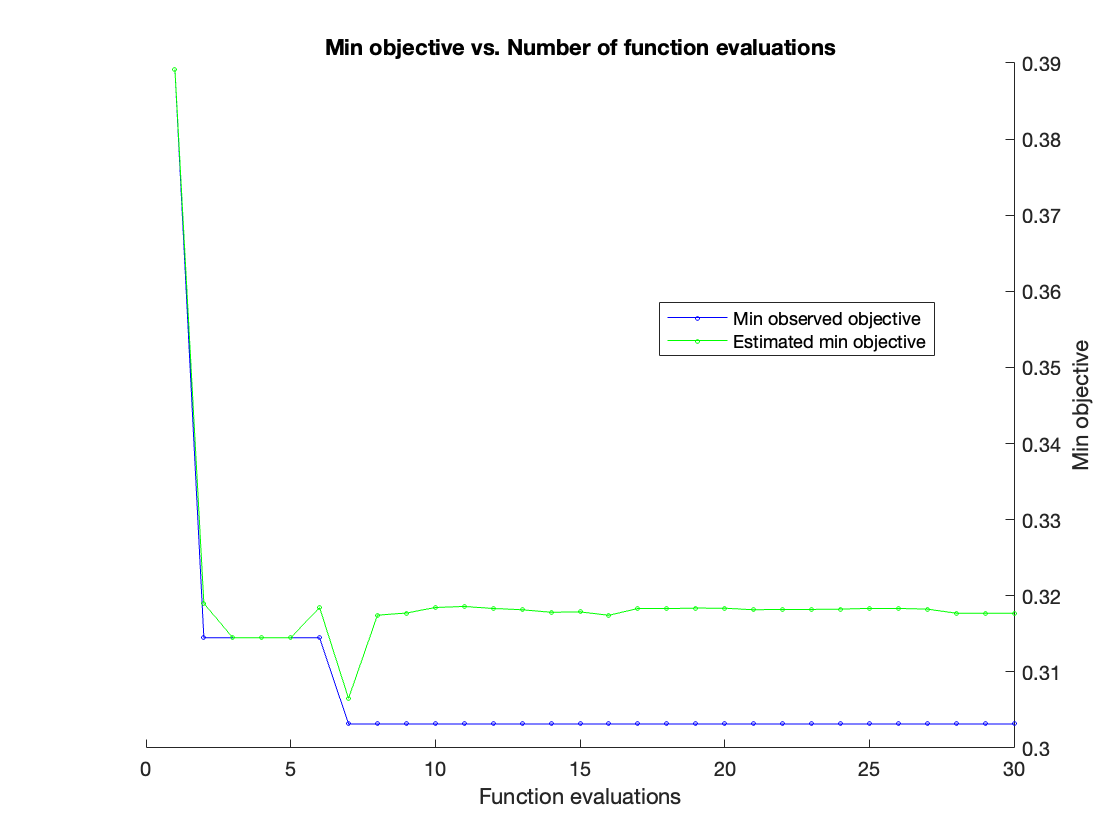

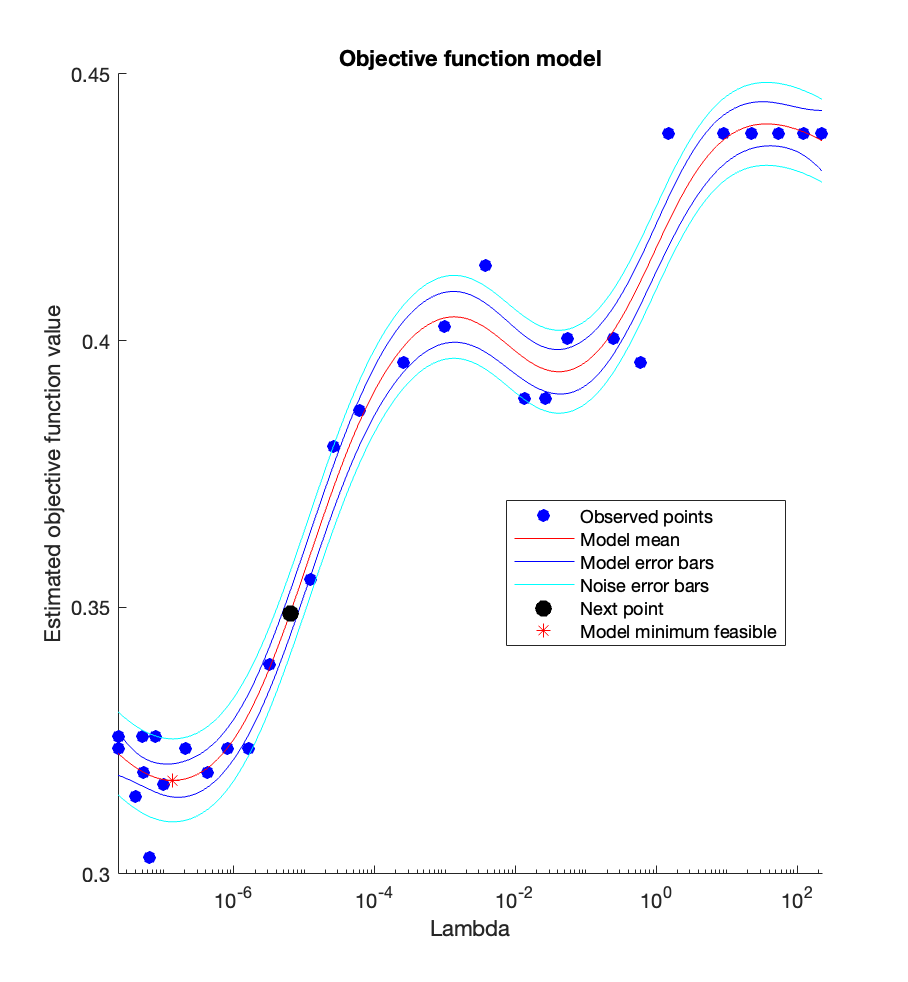


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 22.5501 seconds
Total objective function evaluation time: 8.3676

Best observed feasible point:
      Lambda  
    __________

    6.3169e-08

Observed objective function value = 0.30317
Estimated objective function value = 0.31854
Function evaluation time = 0.30764

Best estimated feasible point (according to models):
      Lambda  
    __________

    1.0114e-07

Estimated objective function value = 0.31771
Estimated function evaluation time = 0.37309



feat_mx2 = feat_mx(:,out_mx(:,3) > quantile(out_mx(:,3),0.9));
ybool = zeros(size(feat_mx2,1),1);
ybool(num_hc+1:end) = 1;
ybool = logical(ybool);

test_ratio = 0.2;
cv = cvpartition(ybool,'Holdout',test_ratio);
trn_idx = training(cv);
eval_idx = test(cv);

[mdl,fit_info] = fitclinear(feat_mx2(trn_idx,:)',ybool(trn_idx),'ObservationsIn','columns',...
    'Learner','logistic',...
    'OptimizeHyperparameters',{'Lambda'},'HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus'));

yhat = predict(mdl,feat_mx2(eval_idx,:));
c = confusionmat(ybool(eval_idx),yhat);
disp(c)

    34    15
    15    46



statsOfMeasure(c,1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"          34         46         40          40 
    "false_positive"         15         15         15          15 
    "false_negative"         15         15         15          15 
    "true_negative"          46         34         40          40 
    "precision"         0.69388     0.7541    0.72399     0.72727 
    "sensitivity"       0.69388     0.7541    0.72399     0.72727 
    "specificity"        0.7541    0.69388    0.72399     0.72727 
    "accuracy"          0.72727    0.72727    0.72727     0.72727 
    "F-measure"         0.69388     0.7541    0.72399     0.72727 


## PCA Transformation

w = 1./(var(feat_mx2)+eps);
[~,score,~,~,explained] = pca(feat_mx2,'VariableWeights',w);

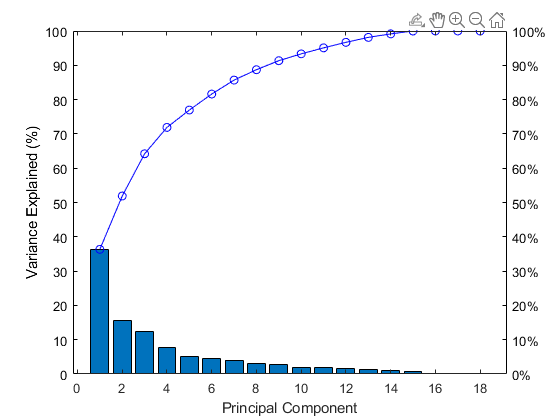

percent_ticks = string(0:10:100);
for i=1:length(percent_ticks)
    percent_ticks(i) = strcat(percent_ticks(i),"%");
end

figure('Color','w')
yyaxis left
bar(explained(1:end))
ylim([0,100])
set(get(gca,'YLabel'), 'String','Variance Explained (%)')
set(gca, 'YColor','black')
yyaxis right
plot(1:18,cumsum(explained(1:end)),'o-','Color','blue')
ylim([0,100])
yticklabels(percent_ticks)
set(gca, 'YColor','black')
xlabel('Principal Component')

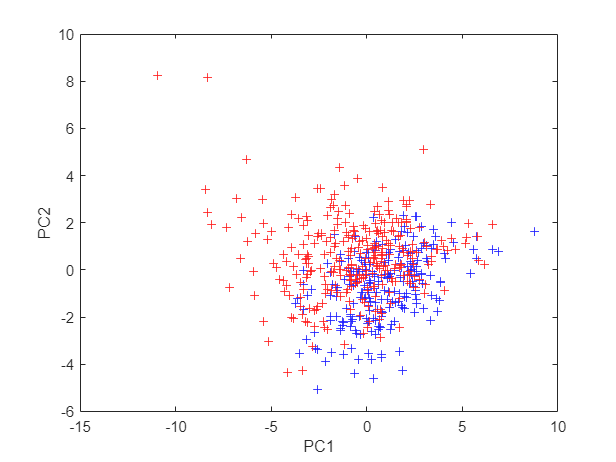

figure('Color','w')
plot(score(1:num_hc,1),score(1:num_hc,2),'+','Color','b')
hold on
plot(score(num_hc+1:end,1),score(num_hc+1:end,2),'+','Color','r')
hold off
xlabel("PC1")
ylabel("PC2")

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Lambda |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.29186 |    0.077466 |     0.29186 |     0.29186 |   0.00010434 |
|    2 | Accept |     0.43891 |    0.062048 |     0.29186 |     0.30092 |       25.954 |
|    3 | Accept |     0.29186 |    0.051398 |     0.29186 |     0.29186 |   1.6058e-06 |
|    4 | Best   |     0.28959 |    0.048402 |     0.28959 |     0.28961 |     0.008247 |
|    5 | Accept |     0.29186 |    0.050903 |     0.28959 |     0.28961 |   2.2682e-08 |
|    6 | Accept |     0.28959 |    0.051732 |     0.28959 |     0.28952 |    0.0014074 |
|    7 | Accept |     0.29186 |     0.05184 |     0.28959 |      0.2895 |   1.5022e-07 |
|    8 | Accept |    

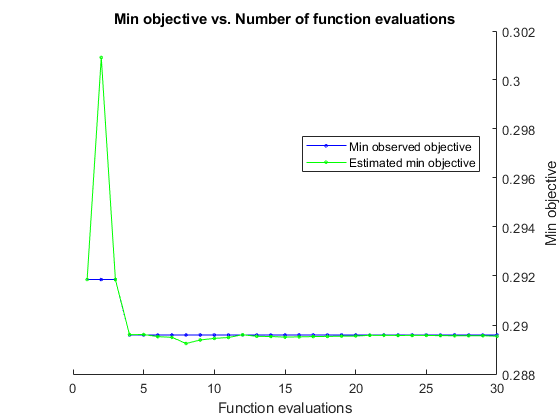

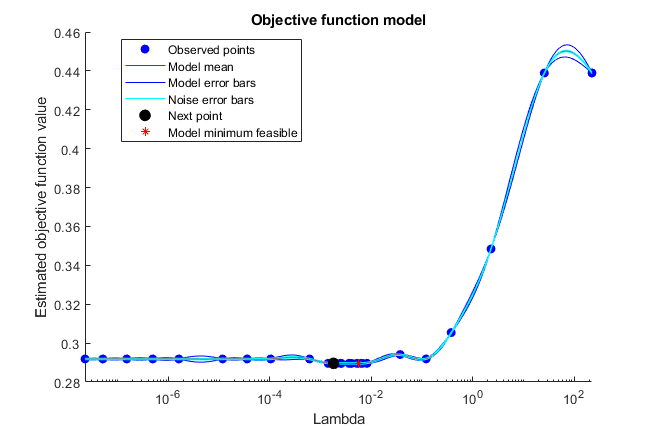


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 9.5177 seconds
Total objective function evaluation time: 1.5957

Best observed feasible point:
     Lambda 
    ________

    0.008247

Observed objective function value = 0.28959
Estimated objective function value = 0.28981
Function evaluation time = 0.048402

Best estimated feasible point (according to models):
     Lambda 
    ________

    0.005243

Estimated objective function value = 0.28954
Estimated function evaluation time = 0.05298



pc_idx = 8;
test_ratio = 0.2;
cv = cvpartition(ybool,'Holdout',test_ratio);
trn_idx = training(cv);
eval_idx = test(cv);

[mdl,fit_info] = fitclinear(score(trn_idx,1:pc_idx)',ybool(trn_idx),'ObservationsIn','columns',...
    'Learner','logistic',...
    'OptimizeHyperparameters',{'Lambda'},'HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus'));

hat = predict(mdl,score(eval_idx,1:pc_idx));
c = confusionmat(ybool(eval_idx),yhat);
disp(c)

    28    21
    10    51



statsOfMeasure(c,1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"          28         51       39.5        39.5 
    "false_positive"         10         21       15.5        15.5 
    "false_negative"         21         10       15.5        15.5 
    "true_negative"          51         28       39.5        39.5 
    "precision"         0.73684    0.70833    0.72259     0.71818 
    "sensitivity"       0.57143    0.83607    0.70375     0.71818 
    "specificity"       0.83607    0.57143    0.70375     0.71818 
    "accuracy"          0.71818    0.71818    0.71818     0.71818 
    "F-measure"         0.64368    0.76692     0.7053     0.71818 
